# Exercício 3

Considere 4 lançamentos de uma moeda equilibrada. Seja X a variável aleatória representativa do

número de coroas observados nos 4 lançamentos.

**Alínea a**

Estime por simulação a função massa de probabilidade px(x) da variável aleatória X.

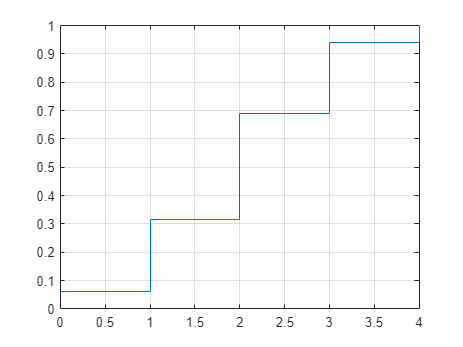

N = 1e5;
numero_lancamentos = 4;
x = 0:numero_lancamentos;

probs = zeros(1,numero_lancamentos + 1); 
lancamentos = rand(4,N);

coroa =  lancamentos <0.5;

for i =0:numero_lancamentos
    cf = sum(coroa)==i;
    probs(i+1) = sum(cf)/N;
    
end

fx = cumsum(probs);

stairs(x,fx)
grid on

**Alínea b**

Estime o valor esperado, a variância e o desvio padrão de X com base em pX(x).

media = sum(x.*probs)

media = 1.9986


variancia = (x-media).^2;

variancia = sum(variancia.*probs)

variancia = 1.0047


variancia2 = sum((x.^2).*probs) - media^2

variancia2 = 1.0047


desvio_padrao = sqrt(variancia)

desvio_padrao = 1.0024

**Alínea c**

Identifique o tipo da distribuição da variável aleatória X e escreva a expressão teórica da respectiva função de probabilidade.

**Alínea d**

Calcule os valores teóricos da função massa de probabilidade de X e compare-os com os valores estimados por simulação obtidos em (a).

p=0.5;
probteorico=zeros(1,5);

for i=0:4
    probteorico(i+1)=prob_teorica(i, 4, p);
end

fx=cumsum(probteorico)

fx =     0.0625    0.3125    0.6875    0.9375    1.0000


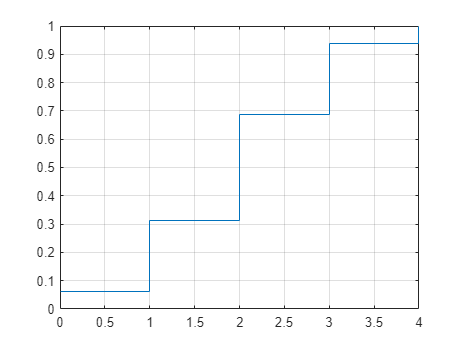

stairs(x,fx);
grid on


%fx simulaçao [0.0621 0.3148 0.6857 0.9367 1.0000]
%fx teorico [0.0625 0.3125 0.6875 0.9375 1.0000]


function p = prob_teorica(k,n,p)

    p= nchoosek(n,k)*p^k*(1-p)^(n-k); 

end
